clc;
clear;
close all;
format shortG;

% Données orbitales initiales

G = 6.6738e-20; % constante gravitationnelle
M = 7.3477e22; % masse de l'astre kg
mu = G*M;
a = 2500; % grand axe km
r_astre = 1736; %km
e = 0.12; % Excentricité de l'orbite
i = 54; % Inclinaison de l'orbite en degrés
omega = 105; % Argument du périastre en degrés
l_omega = 155; % longitude géographique du noeud ascendant
T_astre = 27.321582*24*60*60;

**QUESTION 1 :** Calculer le moyen mouverment (n) en rad/s.

n = sqrt(mu / a^3); % rad/s

fprintf(['Nous avons le moyent mouvement = ', num2str(n), ' rad/s.']);

Nous avons le moyent mouvement = 0.00056021 rad/s.

**QUESTION 2 : **Calculer l'anomalie vraie critique (Theta_critique) en degrés.

theta_crit = acosd(-e); % deg

fprintf(['Nous avons theta critique = ', num2str(theta_crit), ' deg.']);

Nous avons theta critique = 96.8921 deg.

**QUESTION 3 :** Calculer le temps de passage au périgée (tp) en seconde.

E_NA = asind((sqrt(1-e^2)*sind(-omega))/(1+e*cosd(-omega)));

tp = -(1/n)*(deg2rad(E_NA)- e*sind(E_NA)); % secondes

fprintf(['Nous avons tp  = ', num2str(tp), ' s.']);

Nous avons tp  = 2335.3145 s.

**QUESTION 4 :** Calculer aux points de l'orbite d'anomalie vraie Theta comprise entre -780° et 780° par pas de 5° les éléments suivants :

    -    Le temps de passage du satellite (en s)

    -    L'altitude (en km)

    -    La vitesse du satellite (en m/s)

theta = -780:5:780;

t = t_theta(theta, theta_crit, e, n, tp);
figure('Name','temps de passage en fonction de theta');
plot(theta,t);

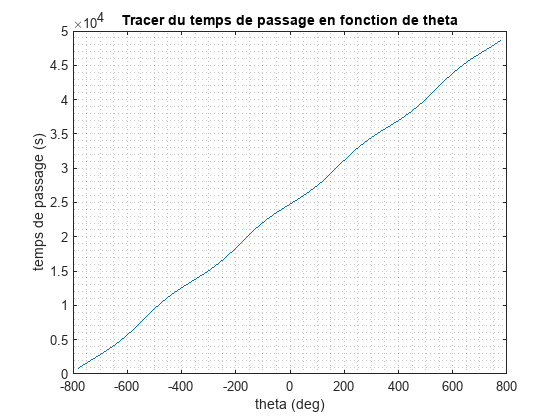

title('Tracer du temps de passage en fonction de theta');
xlabel('theta (deg)');
ylabel('temps de passage (s)');
grid minor;

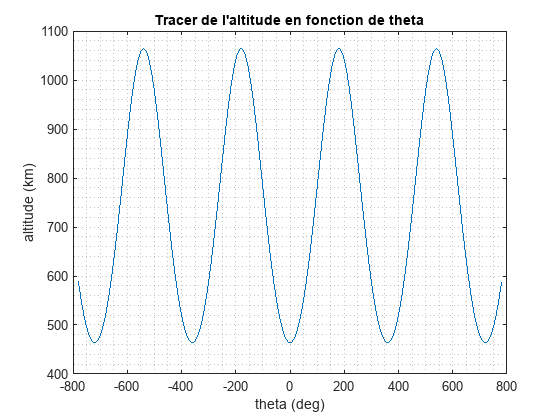

r = a*(1-e^2)./(1+e*cosd(theta));
alt = r - r_astre;
figure('Name','altitude en fonction de theta');
plot(theta, alt);
title("Tracer de l'altitude en fonction de theta");
xlabel('theta (deg)');
ylabel('altitude (km)');
grid minor;

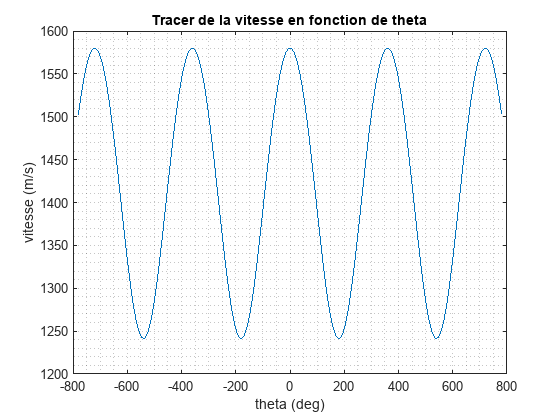

v = sqrt(2*mu*((1./(r))-(1/(2*a))))*1000;
figure('Name','vitesse en fonction de theta');
plot(theta, v);
title('Tracer de la vitesse en fonction de theta');
xlabel('theta (deg)');
ylabel('vitesse (m/s)');
grid minor;

**QUESTION 5 :** Calcul de la latitude, L0 et de la longitude.

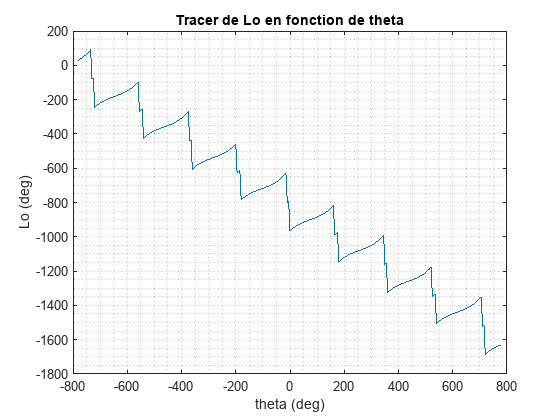

[lat, lo] = lat_lo_theta(theta,omega,i);
figure('Name','Lo en fonction de theta');
plot(theta, lo);
title('Tracer de Lo en fonction de theta');
xlabel('theta (deg)');
ylabel('Lo (deg)');
grid minor;

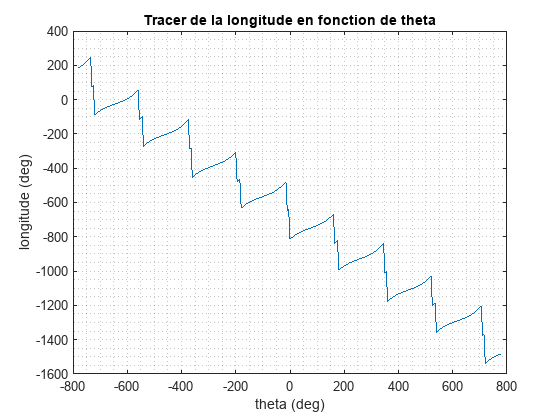



lon = lon_theta(l_omega,lo,t,T_astre);
figure('Name','Longitude en fonction de theta');
plot(theta, lon);
title('Tracer de la longitude en fonction de theta');
xlabel('theta (deg)');
ylabel('longitude (deg)');
grid minor;

**QUESTION 6 :** Tracer de  la trace de l'orbite sur un planisphère vénus.

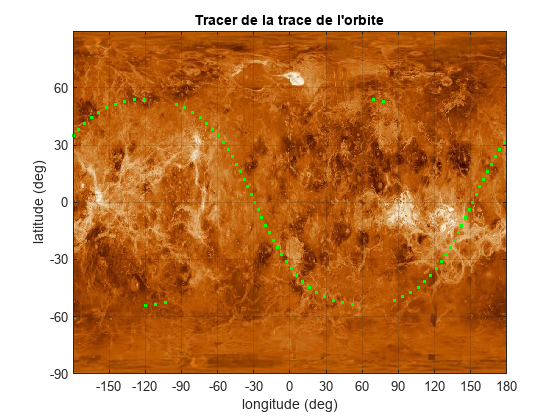

venus = imread('venus_plan.jpeg');
lv = size(venus,1);
lh = size(venus,2);

lats = (1:lv)*180/lv - 90;
lons = (1:lh)*360/lh - 180;

image(lons, -lats, venus)
hold on;
set(gca, 'ydir', 'normal');
grid on;

plot(lon+360*2,lat,'.g');

set(gca, 'XTick',-180:30:180);
set(gca, 'YTick',-90:30:90);

title("Tracer de la trace de l'orbite");
xlabel('longitude (deg)');
ylabel('latitude (deg)');

hold off;

**QUESTION 7 :** Determination du temps de passage, la latitude et la longitude des différents apoastres de l'orbite ainsi que la vitesse du satellite à ces apoastres.

index = find(v==min(v));

for i = 1:length(index)
    
    fprintf(['Pour notre ', num2str(i), ' eme apoastre, on a :']);
    
    fprintf(['temps = ', num2str(t(index(i))), ' s.']);
    fprintf(['latitude = ', num2str(lat(index(i))), ' deg.']);
    fprintf(['longitude = ', num2str(lon(index(i))), ' deg.']);
    fprintf(['vitesse = ', num2str(v(index(i))), ' m/s.']);

end

Pour notre 1 eme apoastre, on a :

temps = 7943.1799 s.

latitude = -51.3936 deg.

longitude = -271.7049 deg.

vitesse = 1241.4368 m/s.

Pour notre 2 eme apoastre, on a :

temps = 19158.9108 s.

latitude = -51.3936 deg.

longitude = -633.4154 deg.

vitesse = 1241.4368 m/s.

Pour notre 3 eme apoastre, on a :

temps = 30374.6417 s.

latitude = -51.3936 deg.

longitude = -995.1258 deg.

vitesse = 1241.4368 m/s.

Pour notre 4 eme apoastre, on a :

temps = 41590.3725 s.

latitude = -51.3936 deg.

longitude = -1356.8363 deg.

vitesse = 1241.4368 m/s.

**QUESTION 8 :** Determination du temps de passage, la latitude et la longitude des différents périastres de l'orbite ainsi que la vitesse du satellite à ces périastres.

index = find(v==max(v));

for i = 1:length(index)
    
    fprintf(['Pour notre ', num2str(i), ' eme périastre, on a :']);
    
    fprintf(['temps = ', num2str(t(index(i))), ' s.']);
    fprintf(['latitude = ', num2str(lat(index(i))), ' deg.']);
    fprintf(['longitude = ', num2str(lon(index(i))), ' deg.']);
    fprintf(['vitesse = ', num2str(v(index(i))), ' m/s.']);

end

Pour notre 1 eme périastre, on a :

temps = 2335.3145 s.

latitude = 51.3936 deg.

longitude = -90.8497 deg.

vitesse = 1580.0105 m/s.

Pour notre 2 eme périastre, on a :

temps = 13551.0453 s.

latitude = 51.3936 deg.

longitude = -452.5601 deg.

vitesse = 1580.0105 m/s.

Pour notre 3 eme périastre, on a :

temps = 24766.7762 s.

latitude = 51.3936 deg.

longitude = -814.2706 deg.

vitesse = 1580.0105 m/s.

Pour notre 4 eme périastre, on a :

temps = 35982.5071 s.

latitude = 51.3936 deg.

longitude = -1175.981 deg.

vitesse = 1580.0105 m/s.

Pour notre 5 eme périastre, on a :

temps = 47198.238 s.

latitude = 51.3936 deg.

longitude = -1537.6915 deg.

vitesse = 1580.0105 m/s.

**QUESTION 9 :** Points survolés par le satellite (latitude,longitude) aux temps t1=−16000s, t2= 5000s et t3= 12000s.

tps = [-16000; 5000; 12000];    % Temps donné

a = 0;
b = 360;
eps = 1e-8;

for i = 1:length(tps)

    E = dichotomie_survol_satellite(e, n, tps(i), tp, a, b, eps)
    theta_ = rad2deg(2*atand((sqrt(1+e)/sqrt(1-e))*tand(E/2))) - 2*360

    [lat_, lo_] = lat_lo_theta(theta_,omega,i);
    lon_ = lon_theta(l_omega,lo_,tps(i),T_astre);

    %fprintf('Latitude à t = %.2f sec : Lat = %.6f deg\n', tps(i), lat_);
    %fprintf('Longitude à t = %.2f sec : Lon = %.6f deg\n', tps(i), lon_);
    
    
end

E =           360


theta_ =          -720


E =        1.4062


theta_ =        -629.1


E =        2.8125


theta_ =       -538.21



% -530  -340

function t = t_theta(theta, theta_crit, e, n, tp)

%---------------------------------------------------------------------------------
%
%                                       function t_theta
%
% calcule le temps t associé à une anomalie vraie theta pour un satellite en orbite 
% elliptique autour de vénus.
%
% inputs            description                                         distance/unités
%   theta           - anomalie vraie                                    - -780 to 780 deg
%   theta_crit      - angle définissant le point de rencontre entre     - deg
%                     l'ellipse et la droite reliant le centre de la 
%                     planète et le point de départ du satellite.   
%   e               - excentricité de l'orbite                          - cte
%   n               - moyen mouverment                                  - rad/s
%   tp              - temps de passage au periastre                     - sec
%
% outputs           :
%   lat             - latitude                                          - deg
%   lo              - longitude vraie initiale                          - deg
%
% locals            :
%   theta_modified  - valeurs de theta ramenées entre -180 et 180 deg   - cte
%   t               - moments/temps                                     - sec
%   correction      - correction appliquée a chaque révolution          - deg
%   flag            - booléen pour corriger les pics                    - true/false
%   E               - anomalie excentrique a un moment donné            - deg
%
%---------------------------------------------------------------------------------

    theta_modified = wrapTo180(theta);
    t = zeros(length(theta),1);

    correction = 0;

    flag = false;

    for i = 1:length(theta)

        if (mod(theta(i), 180) == 0) && (mod(theta(i), 360) ~= 0)

            if theta(i) < 0

                correction = correction + 360;

            else
                flag = true;
            end
            
        end

        E = asind((sqrt(1-e^2)*sind(theta(i)))/(1+e*cosd(theta(i))));
    
        if theta_modified(i) < -theta_crit
            
            t(i) = (1/n)*(deg2rad(correction-180-E)-e*sind(E)) + tp;
    
        elseif -theta_crit < theta_modified(i) && theta_modified(i) < theta_crit
        
            t(i) = (1/n)*(deg2rad(E + correction)-e*sind(E)) + tp;
    
        else

            t(i) = (1/n)*(deg2rad(correction + 180 - E)-e*sind(E)) + tp;

        end 

        if flag
            correction = correction + 360;
            flag = false;
        end

    end

end


%---------------------------------------------------------------------------------
%
%                                       function lat_lo_theta
%
% calcule la latitude et la longitude vraie initiale de l'objet céleste pour différentes 
% anomalie vraie en appliquant une correction si nécéssaire.
%
% inputs            description                                         distance/unités
%   theta           - anomalie vraie                                    - -780 to 780 deg
%   omega           - argument du périastre                             - deg
%   i               - inclinaison de l'orbite en degrés                 - deg
%
% outputs           :
%   lat             - latitude                                          - deg
%   lo              - longitude vraie initiale                          - deg
%
% locals            :
%   correction      - correction appliquée a chaque révolution          - deg
%   flag            - booléen pour corriger les pics                    - true/false
%
%---------------------------------------------------------------------------------

function [lat, lo] = lat_lo_theta(theta,omega,i)
    
    lat = zeros(length(theta),1);
    lo = zeros(length(theta),1);

    correction = 0;

    for x = 1:length(theta)

        if (mod(theta(x), 180) == 0)
            correction = correction - 180; 
        end

        lat(x) = asind(sind(theta(x) + omega)*sind(i));
        lo(x) = atand(tand(theta(x) + omega)*cosd(i)) + correction;

    end

end

%---------------------------------------------------------------------------------
%
%                                       function lon
%
% calcule la longitude de l'objet céleste à différents moments 't' en utilisant l'angle 
% de précession moyen et la longitude vraie initiale de l'objet.
%
% inputs            description                                         distance/unités
%   t               - moments/temps                                     - sec
%   lo              - longitude vraie initiale                          - deg
%   T_astre         - periode de l'objet celestre                       - s^-1
%   l_omega         - longitude géographique du noeud ascendant         - deg
%
% outputs           :
%   lon             - longitude                                         - deg
%
% locals            :
%   alpha_dot       - avance de la longitude vraie                      - cte
%
%---------------------------------------------------------------------------------

function lon = lon_theta(l_omega,lo,t,T_astre)

    lon = zeros(length(t),1);

    alpha_dot = 360/T_astre;

    for i = 1:length(t)

        lon(i) = l_omega + lo(i) - alpha_dot*t(i);

    end   

end

%---------------------------------------------------------------------------------
%
%                                       function y
%
% équation transcendentale E−e sin E = n (t − tp) pour trouver l'anomalie excentrique 
% correspondante
%
% inputs            description                                         distance/unités
%   E               - anomalie excentrique                              - deg
%   t               - moments/temps                                     - sec
%   e               - excentricité de l'orbite                          - cte
%   n               - moyen mouverment                                  - rad/s
%   tp              - temps de passage au periastre                     - sec
%
% outputs           :
%   y               - anomamlie excentrique solution de l'équation      - deg
%
%---------------------------------------------------------------------------------

function y = f(E, e, n, t, tp)
    y = E-e*sind(E)-n*(t-tp);
end

%---------------------------------------------------------------------------------
%
%                          function dichotomie_survol_satellite
%
% implémentation de la méthode de dichotomie pour résoudre l'équation transcendantale 
% E - e*sin(E) = n*(t-tp) afin de trouver l'anomalie excentrique correspondante à un 
% instant de temps t donné pour un satellite en orbite.
%
% renvoie la valeur de E correspondant à la valeur moyenne m de l'intervalle final.
%
% inputs            description                                         distance/unités
%   a, b            - bornes inférieure et supérieure de l'intervalle   - none
%   t               - moments/temps                                     - sec
%   eps             - précision souhaitée pour la solution              - none
%   e               - excentricité de l'orbite                          - cte
%   n               - moyen mouverment                                  - rad/s
%   tp              - temps de passage au periastre                     - sec
%
% outputs           :
%   E               - anomamlie excentrique solution de l'équation      - deg
%
% locals            :
%   m               - valeur moyenne de l'intervalle                    - none
%
%---------------------------------------------------------------------------------

function z = dichotomie_survol_satellite(e, n, t, tp, a, b, eps)

    while b-a > eps

        m = (a+b)/2;

        if f(a, e, n, t, tp)*f(b, e, n, t, tp) <= 0
            b = m;
        else
            a = m;
        end

    end

    z = m;

end